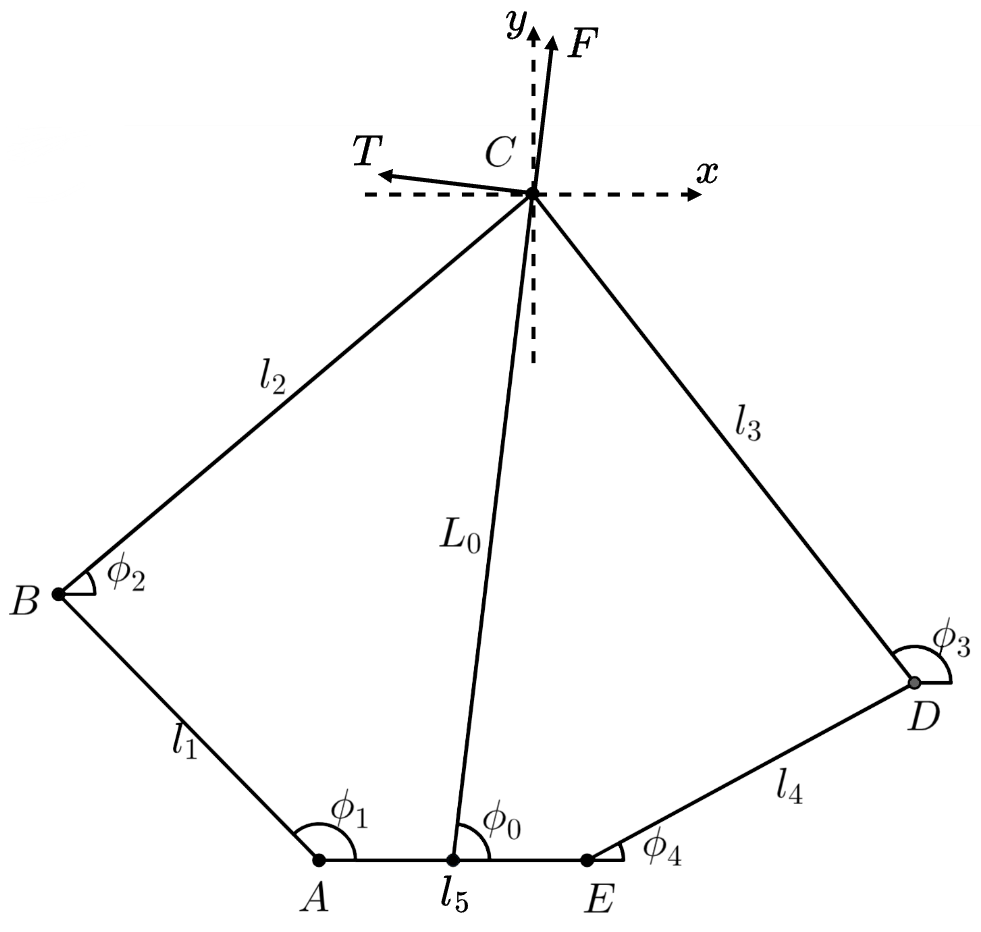

% 本篇根据：《五连杆解算与VMC》写成

% VMC：将工作空间的力/力矩转化成关节空间的力/力矩
% 在平衡步兵建模时，我们将腿部简化为了一根摆杆
% 现在我们利用VMC，把简化后的力变回两个关节电机的力矩

% 直接用运动学结果（即五连杆解算最后得到的L0、phi0关于phi1、phi4的式子）
% （详情可见BanlanceSoldier_5LianGan的正或逆运动学）求偏导过于复杂，
% 无法简便地进行计算，所以采用速度关系来进行求解

clear; clc;
% 参数定义
syms phi_1(t)  phi_2(t)  phi_3(t)  phi_4(t)
syms l_1  l_2  l_3  l_4  l_5

% l_1 = 210;  l_2 = 250; % l_1大腿，l_2小腿
% l_4 = l_1;  l_3 = l_2;
% l_5 = 0;               % l_5同侧关节间距

% 根据式子1.1求导，得到2.7
% 进而解出phi2_dot

syms xB0(t)  yB0(t)  xD0(t)  yD0(t) % 这里的0代表临时变量，没有特殊含义
% 式子1.1：左右列写xC和yC
equ1_1 = [ ...
    xB0 + l_2*cos(phi_2) == xD0 + l_3*cos(phi_3), ...
    yB0 + l_2*sin(phi_2) == yD0 + l_3*sin(phi_3), ...
];

equ2_7 = diff(equ1_1,t);

syms phi_dot_20   phi_dot_30 % 这里的0代表临时变量，没有特殊含义
equ2_7 = subs(equ2_7, {diff(phi_2,t), diff(phi_3,t)}, ...
                      {phi_dot_20,    phi_dot_30});

[phi_dot_2,phi_dot_3] = solve(equ2_7,phi_dot_20,phi_dot_30);

xB = l_1*cos(phi_1);            yB = l_1*sin(phi_1);
xD = l_5 + l_4*cos(phi_4);      yD = l_4*sin(phi_4);
xB_dot = diff(xB,t);          yB_dot = diff(yB,t);
xD_dot = diff(xD,t);          yD_dot = diff(yD,t);

phi_dot_2 = subs(phi_dot_2, ...
                {diff(xB0,t), diff(yB0,t), diff(xD0,t), diff(yD0,t)}, ...
                {xB_dot,      yB_dot,      xD_dot,      yD_dot});

% 根据1.1求导，得到2.6
% 将上一步得到的phi2_dot代入

xC = l_1*cos(phi_1) + l_2*cos(phi_2);
yC = l_1*sin(phi_1) + l_2*sin(phi_2);

xC_dot = diff(xC,t);
yC_dot = diff(yC,t);

xC_dot = subs(xC_dot,diff(phi_2,t),phi_dot_2);
yC_dot = subs(yC_dot,diff(phi_2,t),phi_dot_2);

% 求xC_dot、yC_dot关于phi_dot_1、phi_dot_4的雅各比矩阵
% 得到它们的映射关系
syms phi_dot_1  phi_dot_4
xC_dot = subs(xC_dot, {diff(phi_1,t), diff(phi_4,t)},...
                      {phi_dot_1,     phi_dot_4});
yC_dot = subs(yC_dot, {diff(phi_1,t), diff(phi_4,t)},...
                      {phi_dot_1,     phi_dot_4});

x_dot = [xC_dot; yC_dot];
q_dot = [phi_dot_1; phi_dot_4];
x_dot = simplify(collect(x_dot,q_dot));
J = simplify(jacobian(x_dot,q_dot));

% 上面的雅各比矩阵是C点直角坐标与phi1、phi4的对应关系
% 即Fx、Fy与T1、T2之间的关系
% 我们需要进一步将其转化为沿杆的力与力矩(F、Tp)与T1、T2之间的关系

根据虚功原理，有             

写成矩阵形式就是          

等价形式为               

利用上文的雅各比代入得    

所以                          

两边同时转置得                   

% 旋转矩阵R如何得到
% 注意，虽然我这里写的旋转矩阵R与文章中的不太一样，但其实是相同的
% 不信的话可以用高中的三角函数知识自己变个形

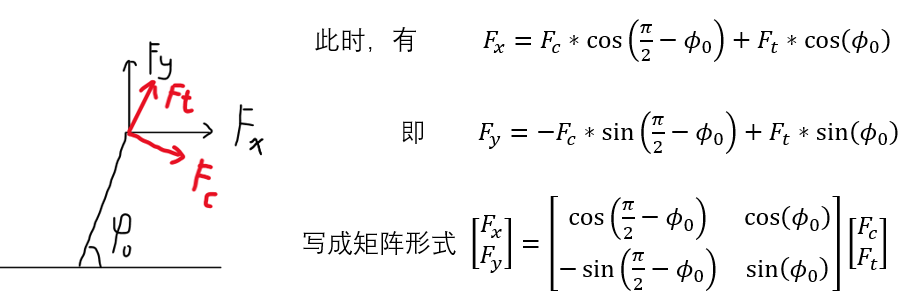

% 变换矩阵M如何得到

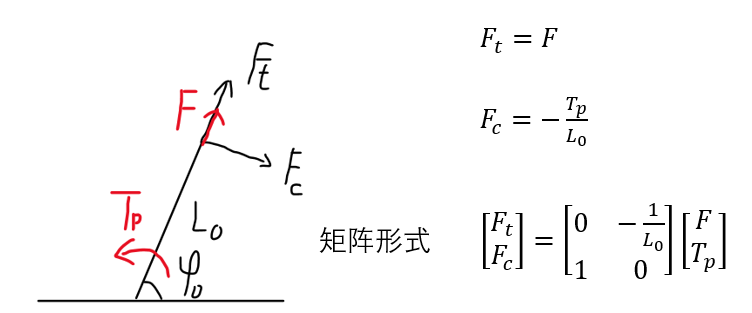

最后我们可以得到   

syms phi0  L0
JT = J.'; % J的转置
R = [cos(pi/2 - phi0)  cos(phi0);
     -sin(pi/2 - phi0) sin(phi0)];
M = [0 -1/L0;
     1   0  ];
T = simplify(JT*R*M) % 最后的VMC转化矩阵

$$T(t) = \begin{array}{l} \left(\begin{array}{cc} -\frac{l_{1}\,\sin\left(\varphi_{0}-\varphi_{3}\left(t\right)\right)\,\sigma_{3}}{\sigma_{1}} & -\frac{l_{1}\,\cos\left(\varphi_{0}-\varphi_{3}\left(t\right)\right)\,\sigma_{3}}{L_{0}\,\sigma_{1}}\\ -\frac{l_{4}\,\sin\left(\varphi_{0}-\varphi_{2}\left(t\right)\right)\,\sigma_{2}}{\sigma_{1}} & -\frac{l_{4}\,\cos\left(\varphi_{0}-\varphi_{2}\left(t\right)\right)\,\sigma_{2}}{L_{0}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\varphi_{2}\left(t\right)-\varphi_{3}\left(t\right)\right)\\ \sigma_{2}=\sin\left(\varphi_{3}\left(t\right)-\varphi_{4}\left(t\right)\right)\\ \sigma_{3}=\sin\left(\varphi_{1}\left(t\right)-\varphi_{2}\left(t\right)\right) \end{array}$$